# HW1：HuBMAP - Hacking the Human Vasculature

作者：資工二 412210037 林威岑

% 有需要可以先清空資料
clear

## 1. Upload Training Data 

我預設是將這份程式碼放在老師提供的資料夾下，並且已經解壓縮過，所以會直接從這份檔案的位置抓到其他test,json,train,csv等資料。

匯入訓練集資料，包含1500張訓練集的TIF照片，以及對應的1500份json檔案。而其中因為只有來自第一個資料集所標註的資料可信度大，所以我並不打算採用WSI的第二個資料集做使用。

% 找到目前檔案的位置
currentFile = matlab.desktop.editor.getActiveFilename;
currentFolder = fileparts(currentFile);

% 設定train,json檔案的路徑
trainFolder = fullfile(currentFolder,"train");
jsonFolder = fullfile(currentFolder, "json");
train_img = dir(fullfile(trainFolder, '*.tif'));

% 預先分配儲存資料的空間
train_num = length(train_img);
imageData = cell(1, train_num);  
jsonData = cell(1, train_num);
data_num = 1;

% 先匯入資料集中的資料，方便我們在讀取的時候直接篩選
metaData = readtable("tile_meta.csv");

% 讀取所有圖片,json並儲存到 cell array
for i = 1:train_num
    imagePath = fullfile(trainFolder, train_img(i).name); % 取得照片的路徑
    id = extractBefore(train_img(i).name, '.tif');
    col_idx = find(strcmp(metaData{:,1}, id));
    if(metaData{col_idx,3}==1) % 只讀取第一個資料集的資料
        % 讀取圖片
        imageData{data_num} = imread(imagePath);

        % 讀取 json檔案
        jsonName = strcat(id, '.json'); % 將照片檔名轉成json檔名
        jsonPath = fullfile(jsonFolder, jsonName); % 取的json的路徑
        jsonText = fileread(jsonPath);
        jsonData{data_num} = jsondecode(jsonText); % 解析 JSON
        data_num = data_num+1;
    end
end

data_num = data_num-1;
fprintf("upload all tif img\n");

upload all tif img


## 2. Label The Training Data by Json File

% 定義標籤類別與固定顏色 (RGB 格式，範圍 0~1)
class_type = ["blood_vessel", "glomerulus", "unsure"];
class_colors = [0 255 0;   % blood_vessel (綠色：想要的區域)
                255 0 0;   % glomerulus (紅色：不想要的區域)
                255 255 0];  % unsure (亮黃色：不重要)

 % 設定遮罩的透明度
alpha = 0.7;

% 初始化 Mask, GroundTruth 照片
annotationMasks = cell(1, data_num);  % 建立一個長度為 290 的 cell 陣列
annotatedImage = cell(2, data_num); % (1,:)是直接覆蓋區域的圖；(2,:)的遮罩會呈現半透明

for i = 1:data_num
    annotationMasks{i} = zeros(512, 512, 'uint8');  % 每個 cell 存一個 512×512 的 mask
    annotatedImage{1,i} = imageData{i}; % 將 annotatedImage 初始化為原始圖像
    annotatedImage{2,i} = imageData{i};
end


for i=1:data_num    
    % 讀取json檔案
    data = jsonData{i};
    
    % 解析 JSON 標註
    annotation_num = length(data.annotations);
    
    for j = 1:annotation_num
        annotation = data.annotations(j);
        labelType = annotation.type; % 例如 'glomerulus'
        classIndex = find(ismember(class_type, labelType));
    
        % 提取標註的座標
        coordinates = annotation.coordinates; % 取得像素點
        Points_num = length(coordinates);
        x = coordinates(:,:,1); % x 座標
        y = coordinates(:,:,2); % y 座標
    
        annotationMasks{i} = annotationMasks{i} + uint8(poly2mask(x,y,512,512))*classIndex;
    end
                
    % 將 RGB 顏色套用到對應的標籤
    for j = 1:3
        % 找出對應標籤的位置
        mask = (annotationMasks{i} == j);
            
        % 將對應位置的 RGB 值改為指定顏色
        annotatedImage{1,i}(repmat(mask, [1 1 3])) = repmat(class_colors(j,:), [sum(mask(:)), 1]);
        for c = 1:3
                color = double(class_colors(j, c));  % 轉換顏色為 double
                annotatedImage{2,i}(:,:,c) = uint8( double(annotatedImage{2,i}(:,:,c)) + alpha * color * double(mask) );
        end    
    end
end

#### 以下這一區段程式碼不一定要執行，只是可以讓我們清楚看到標記後的成果，也就是我們的 Ground Truth 資料。

透過賦值 1~289 的數字給 index ，就可以觀察到對應 data 的 Ground Truth 資料。

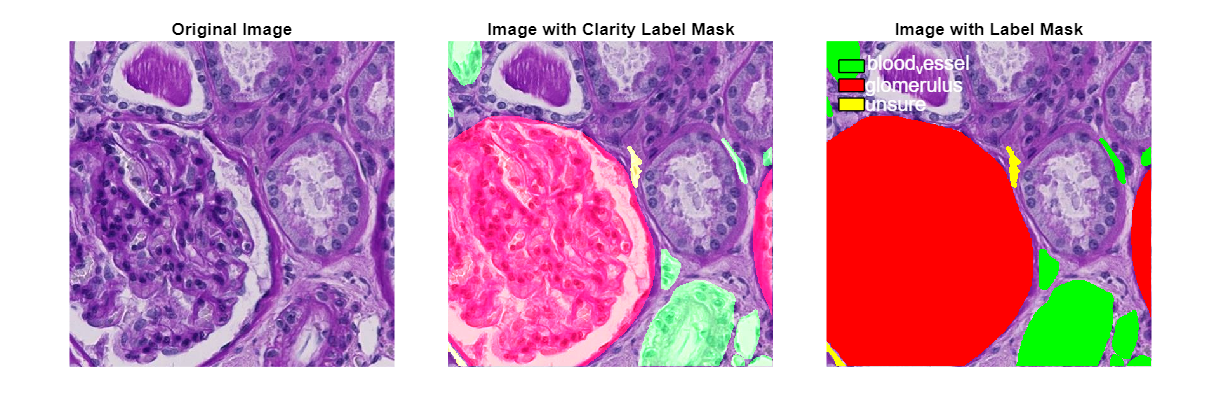

% 顯示某index的圖片
index = 148;
figure;
set(gcf, 'Position', [100, 100, 1200, 400]);  % 增大圖形視窗大小

% 設置圖片顯示區域的大小
subplot('Position', [0.05, 0.1, 0.28, 0.8]);  % 左邊圖形
imshow(imageData{index});
title('Original Image');

subplot('Position', [0.36, 0.1, 0.28, 0.8]);  % 中間圖形
imshow(annotatedImage{2,index});
title('Image with Clarity Label Mask');

subplot('Position', [0.67, 0.1, 0.28, 0.8]);  % 右邊圖形
imshow(annotatedImage{1,index});
title('Image with Label Mask');

% 手動添加 Legend (顯示在圖片外部)
% 設定文字和顏色方塊的起始位置
legend_x = 20;  % x 座標 (將標註置於圖片外側)
legend_y = 30;  % 初始 y 座標
box_height = 20;
box_width = 40;
gap = 10; % 標籤間的間距

for j = 1:3
    % 畫出顏色方塊
    rectangle('Position', [legend_x, legend_y, box_width, box_height], ...
              'FaceColor', class_colors(j,:) / 255, 'EdgeColor', 'k');
    
    % 加上標籤名稱
    text(legend_x + box_width + 0.5, legend_y + box_height / 2, class_type(j), ...
         'Color', 'w', 'FontSize', 12, 'VerticalAlignment', 'middle');
    
    % 調整 y 座標，讓下一個標籤往下排列
    legend_y = legend_y + box_height + gap;
end

hold off;

## 3.  Data Augmentation

數據增強，這是為了拓展我們的訓練資料集，由於現在的訓練資料只有289份，完全不夠我們進行訓練。

所以我們透過旋轉、平移、鏡像新增更多照片到我們的訓練集中。當然label mask的資料也要同步進行增加。

all_data_num = data_num * 6;
trainData = cell(1, all_data_num);
groundTruthData = cell(1, all_data_num);

for i=1:data_num
    trainData{1+(i-1)*6} = imageData{i};
    groundTruthData{1+(i-1)*6} = annotationMasks{i};
end

augmenter_img = imageDataAugmenter('FillValue',0,'RandRotation',[-15,15],'RandScale',[0.8,1.2], 'RandXReflection',true, 'RandYReflection',true);
augmenter_mask = imageDataAugmenter('FillValue',0,'RandRotation',[-15,15],'RandScale',[0.8,1.2], 'RandXReflection',true, 'RandYReflection',true);
% 因為 mask 中本來就有標記的class number
% 分別是1:blood_vessel, 2:glomerulus ,3:unsure，我們將旋轉後產生的黑邊填上第4類，方便我們之後做篩選

for i=1:data_num
    for j=1:5
        augmented_img = augmentedImageDatastore([512,512,3],imageData{i},'DataAugmentation',augmenter_img);
        augmented_mask = augmentedImageDatastore([512,512,3],annotationMasks{i},'DataAugmentation',augmenter_mask);
        trainData{1+(i-1)*6+j} = imtile(preview(augmented_img).input);
        groundTruthData{1+(i-1)*6+j} = imtile(preview(augmented_mask).input);
    end
end

## 4.  Preprocess The Training & Testing Data（我不確定有沒有經過這個處理，判別準確率會不會上升）

接著要將圖片的色彩標準化，在這邊我們使用Vahadane Stain Normalization，因為MATLAB中沒有這個內建的函數，並且這個函數需要跑較久的時間，我有上網查到一個可以使用GPU加速的Vahadane的開源程式碼，我已自行將它下載下來，並且附在這份程式碼的資料夾中，所以可以直接使用。

我打算以測試集資料的第一張照片作為顏色統一的標準...

% 匯入測試集資料
test_imds = imageDatastore('test',"FileExtensions",'.tif');

% 將當前目錄加入python搜尋路徑
% if count(py.sys.path,'') == 0
%     insert(py.sys.path,int32(0),'');
% end

% 需在自己的python環境中下載spams才能正確執行；其實作者也有說可以忽略spams造成的錯誤，不然下載spams很麻煩，會出現一堆錯誤

% 先設定好要輸入的參數（先嘗試做一組）
% osh = trainData{1};
% normalizer = TorchVahadaneNormalizer()
% mask = 1-(groundTruthData{1}==4) % 將旋轉後黑色的部分排除

% 將mask中classtype >1 的都歸類成0
for i=1:data_num
    groundTruthData{i} = (groundTruthData{i}==1);
end

## 5. Split The Data

我們將目前的訓練資料再分成 85%訓練集 以及 15%驗證集，透過隨機抽取。（其實觀察前幾名的做法中，有一位有說到其實他把距離較近的資料分開成訓練集以及驗證集（可能因為相近的架構比較像吧），這樣做才可以讓模型學習到更多不同的照片資訊，不過我沒有這樣做

% 設定隨機種子，確保每次劃分結果一致
rng(0); 

% 產生隨機索引
indices = randperm(all_data_num); 

% 設定 85% 訓練集，15% 驗證集
trainCount = round(0.85 * all_data_num); 

% 劃分訓練集與驗證集
trainIdx = indices(1:trainCount);
valIdx = indices(trainCount+1:end);

trainImages = trainData(trainIdx);
trainMasks = groundTruthData(trainIdx);

valImages = trainData(valIdx);
valMasks = groundTruthData(valIdx);

TrainImgsFolder = 'Train_Imgs_Data';
TrainMasksFolder = 'Train_Masks_Data';
ValImgsFolder = 'Val_Imgs_data';
ValMasksFolder = 'Val_Masks_Data';

if ~exist(TrainImgsFolder, 'dir')
    mkdir(TrainImgsFolder);  % 如果資料夾不存在，創建它
    for i=1:trainCount
        imwrite(trainImages{i}, fullfile(TrainImgsFolder, sprintf('Train_image_%d.tif', i)));
    end
end

if ~exist(TrainMasksFolder, 'dir')
    mkdir(TrainMasksFolder);  % 如果資料夾不存在，創建它
    for i=1:trainCount
        imwrite(trainMasks{i},fullfile(TrainMasksFolder, sprintf('Train_mask_%d.png', i)));
    end
end

if ~exist(ValImgsFolder, 'dir')
    mkdir(ValImgsFolder);  % 如果資料夾不存在，創建它
    for i=1:(all_data_num-trainCount)
        imwrite(valImages{i}, fullfile(ValImgsFolder, sprintf('Val_image_%d.tif', i)));
    end
end

if ~exist(ValMasksFolder, 'dir')
    mkdir(ValMasksFolder);  % 如果資料夾不存在，創建它
    for i=1:(all_data_num-trainCount)
        imwrite(valMasks{i},fullfile(ValMasksFolder, sprintf('Val_mask_%d.png', i)));
    end
end

% classNames = ["background", "blood_vessel", "glomerulus", "unsure", "black_edge"];
% pixelLabelID = [0 1 2 3 4];

classNames = ["background", "blood_vessel"];
pixelLabelID = [0 1];

train_imds = imageDatastore(TrainImgsFolder);
train_pxds = pixelLabelDatastore(TrainMasksFolder, classNames, pixelLabelID);
val_imds = imageDatastore(ValImgsFolder);
val_pxds = pixelLabelDatastore(ValMasksFolder, classNames, pixelLabelID);

dsTrain = pixelLabelImageDatastore(train_imds, train_pxds);
dsVal = pixelLabelImageDatastore(val_imds, val_pxds);

## 6. Setup U-Net Structure

Reference from Compulsory Course for the Undergraduate Students , Lecturer: Chia-Feng Lu (alvin4016@nycu.edu.tw)

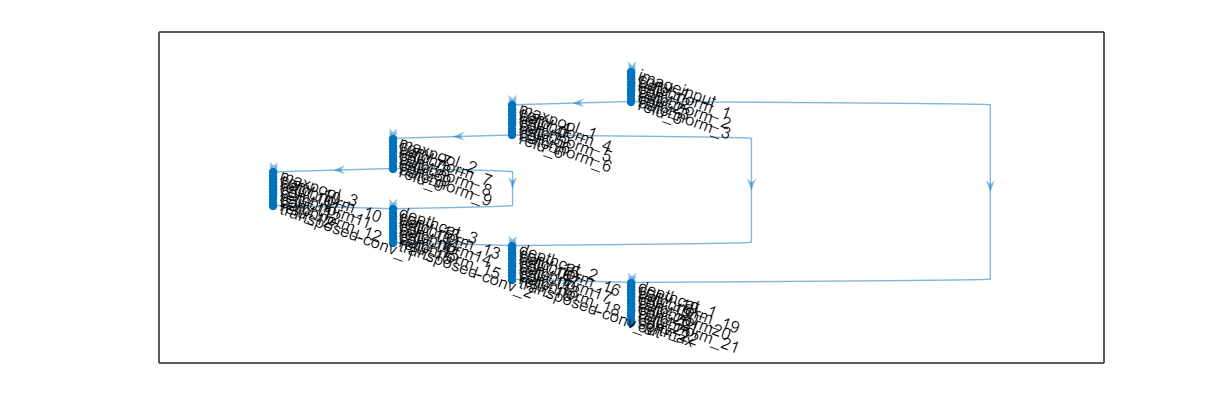

imageSize = [512, 512, 3];  % 圖像尺寸

% 創建一個空的網路結構
lgraph = layerGraph(); 

% classWeights = [0.2, 1.0, 1.0, 1.0, 1.0]; % 降低背景權重，其他類別設為1

% 架構 U-Net 結構
tempLayers = [ % Encoder: 1 depth
    imageInputLayer(imageSize, "Name", "imageinput");
    convolution2dLayer([3 3], 2, "Name","conv_1", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_1");
    reluLayer("Name", "relu_1")

    convolution2dLayer([3 3], 16, "Name","conv_2", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_2");
    reluLayer("Name", "relu_2")

    convolution2dLayer([3 3], 16, "Name","conv_3", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_3");
    reluLayer("Name", "relu_3")];

lgraph = addLayers(lgraph, tempLayers);

tempLayers = [ % Encoder: 2 depth
    maxPooling2dLayer([5 5], "Name", "maxpool_1", "Padding", "same", "Stride", [2 2]);
    convolution2dLayer([3 3], 16, "Name","conv_4", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_4");
    reluLayer("Name", "relu_4")

    convolution2dLayer([3 3], 32, "Name","conv_5", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_5");
    reluLayer("Name", "relu_5")

    convolution2dLayer([3 3], 32, "Name","conv_6", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_6");
    reluLayer("Name", "relu_6")];

lgraph = addLayers(lgraph, tempLayers);

tempLayers = [ % Encoder: 3 depth
    maxPooling2dLayer([5 5], "Name", "maxpool_2", "Padding", "same", "Stride", [2 2])
    convolution2dLayer([3 3], 32, "Name","conv_7", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_7")
    reluLayer("Name", "relu_7")

    convolution2dLayer([3 3], 64, "Name","conv_8", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_8")
    reluLayer("Name", "relu_8")

    convolution2dLayer([3 3], 64, "Name","conv_9", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_9")
    reluLayer("Name", "relu_9")];

lgraph = addLayers(lgraph, tempLayers);

tempLayers = [ % Bridge: 4 depth 
    maxPooling2dLayer([5 5], "Name", "maxpool_3", "Padding", "same", "Stride", [2 2])
    convolution2dLayer([3 3], 64, "Name","conv_10", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_10");
    reluLayer("Name", "relu_10")

    convolution2dLayer([3 3], 128, "Name","conv_11", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm11")
    reluLayer("Name", "relu_11")

    convolution2dLayer([3 3], 128, "Name","conv_12", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_12")
    reluLayer("Name", "relu_12")
    
    transposedConv2dLayer([3 3], 32, "Name", "transposed-conv_1", "Cropping","same","Stride",[2 2])];

lgraph = addLayers(lgraph, tempLayers);

tempLayers = [ % Decoder: 3 depth
    depthConcatenationLayer(2, "Name", "depthcat_3")
    convolution2dLayer([3 3], 64, "Name","conv_13", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_13")
    reluLayer("Name", "relu_13")

    convolution2dLayer([3 3], 64, "Name","conv_14", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm14")
    reluLayer("Name", "relu_14")

    convolution2dLayer([3 3], 64, "Name","conv_15", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_15")
    reluLayer("Name", "relu_15")

    transposedConv2dLayer([3 3], 32, "Name", "transposed-conv_2", "Cropping","same","Stride",[2 2])];

lgraph = addLayers(lgraph, tempLayers);

tempLayers = [ % Decoder: 2 depth
    depthConcatenationLayer(2, "Name", "depthcat_2")
    convolution2dLayer([3 3], 32, "Name","conv_16", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_16")
    reluLayer("Name", "relu_16")

    convolution2dLayer([3 3], 32, "Name","conv_17", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm17")
    reluLayer("Name", "relu_17")

    convolution2dLayer([3 3], 32, "Name","conv_18", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_18")
    reluLayer("Name", "relu_18")

    transposedConv2dLayer([3 3], 32, "Name", "transposed-conv_3", "Cropping","same","Stride",[2 2])];

lgraph = addLayers(lgraph, tempLayers);

tempLayers = [ % Decoder: 1 depth
    depthConcatenationLayer(2, "Name", "depthcat_1")
    convolution2dLayer([3 3], 32, "Name","conv_19", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_19")
    reluLayer("Name", "relu_19")

    convolution2dLayer([3 3], 16, "Name","conv_20", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm20")
    reluLayer("Name", "relu_20")

    convolution2dLayer([3 3], 16, "Name","conv_21", "Padding", "same")
    batchNormalizationLayer("Name", "batchnorm_21")
    reluLayer("Name", "relu_21")

    convolution2dLayer([3 3], 2, "Name","conv_22", "Padding", "same")
    softmaxLayer("Name","softmax")
    dicePixelClassificationLayer('Name', 'out')]; % 使用 Dice Loss 適合不均衡分割
    % pixelClassificationLayer('Name','out','Classes',classNames,'ClassWeights',classWeights)]; % 因為過度於擬合背景，所以重新分配權重
    % pixelClassificationLayer("Name", "pixel-class")]; % 原本的

lgraph = addLayers(lgraph, tempLayers);

clear tempLayers

lgraph = connectLayers(lgraph, "relu_3", "maxpool_1");
lgraph = connectLayers(lgraph, "relu_3", "depthcat_1/in1");
lgraph = connectLayers(lgraph, "relu_6", "maxpool_2");
lgraph = connectLayers(lgraph, "relu_6", "depthcat_2/in1");
lgraph = connectLayers(lgraph, "relu_9", "maxpool_3");
lgraph = connectLayers(lgraph, "relu_9", "depthcat_3/in1");
lgraph = connectLayers(lgraph, "transposed-conv_1", "depthcat_3/in2");
lgraph = connectLayers(lgraph, "transposed-conv_2", "depthcat_2/in2");
lgraph = connectLayers(lgraph, "transposed-conv_3", "depthcat_1/in2");

clf; %  清除之前的圖
plot(lgraph);

analyzeNetwork(lgraph);

options = trainingOptions('sgdm', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 16, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'LearnRateDropPeriod', 10, ...
    'DispatchInBackground', true, ...
    'ExecutionEnvironment', "GPU", ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ValidationData', dsVal);  % 如果有驗證資料

## 7. Start Training with U-Net

Starting parallel pool (parpool) using the 'Processes' profile ...
02-Apr-2025 14:11:48: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 4 workers.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:03 |       67.00% |       66.26% |       0.8526 |       0.8093 |          0.0010 |
|       1 |          50 |       00:18:42 |       86.03% |       85.52% |       0.7883 |       0.7809 |          0.0010 |
|       2 |         100 |       00:36:

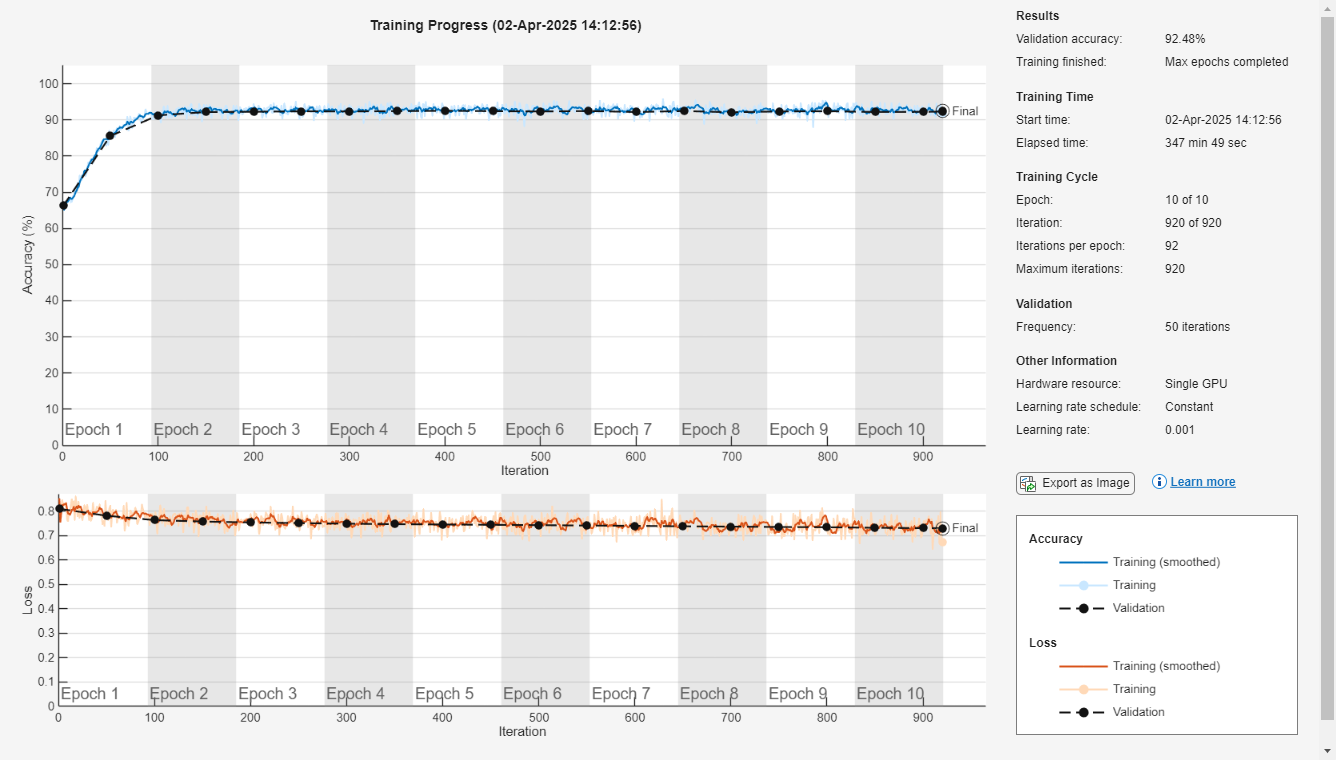

reset(gpuDevice);  % 重置 GPU

modelDateTime = string(datetime('now', 'Format','yyyy-MM-dd-HH-mm'));
[model, info] = trainNetwork(dsTrain, lgraph, options);

save(strcat('trainedModel', modelDateTime, '.mat'), 'model'); % 將跑好的model存取下來

## 8. Predict the testing data

% load('trainedModel-XXXX-XX-XX-XX-XX.mat', 'net', 'options'); % 存取之前存下來的model，中間記得改成對應的時間
load('trainedModel2025-04-02-14-10.mat', 'model');
Result = predict(model, test_imds);

## 9. Transfer Predict Results to Label Data

% 重新定義標籤類別與顏色 (RGB 格式，範圍 0~255)
class_colors = [0 255 0];    % 1 = blood_vessel (綠色)

% 設定遮罩的透明度
alpha = 0.7;

numImages = size(Result, 4); % 取得第四維度的資料：總影像數量

% 設定輸出資料夾
predictJsonsFolder = 'Predicted_json/';
if ~exist(predictJsonsFolder, 'dir')
    mkdir(predictJsonsFolder); % 建立資料夾（如果不存在）
end

predictImagesFolder = 'Predicted_images/';
if ~exist(predictImagesFolder, 'dir')
    mkdir(predictImagesFolder); % 建立資料夾（如果不存在）
end

testFolder = dir(fullfile('test','*.tif'));

% 初始化 Mask 和 結果 照片
predictedMasks = cell(1, numImages);  % 建立一個長度為 290 的 cell 陣列
predictedImage = cell(2, numImages); % (1,:)是直接覆蓋區域的圖；(2,:)的遮罩會呈現半透明

for i = 1:numImages
    predictedMasks{i} = zeros(512, 512, 'uint8');  
    predictedImage{1,i} = test_imds.readimage(i);
    predictedImage{2,i} = test_imds.readimage(i);
end

for i = 1:numImages
    singleImageMask = Result(:, :, :, i); % 取出第 i 張影像的預測結果
    [~, predictedMasks{i}] = max(singleImageMask, [], 3); % 取機率最高的類別索引
    predictedMasks{i} = uint8(predictedMasks{i});  % 轉成 uint8
   
    mask = (predictedMasks{i} == 2);  % 找出標籤 1 的區域
    [y, x] = find(mask == 1);

    % 建立 JSON 結構
    jsonStruct = struct();
    jsonStruct.type = "blood_vessel";
    jsonStruct.coordinates = [x, y];  % 存成 (x, y) 格式
    jsonText = jsonencode(jsonStruct);% 轉換成 JSON 字串
    % 設定 JSON 檔名
    fileName = erase(testFolder(i).name,'.tif');
    jsonFileName = fullfile(predictJsonsFolder, [fileName, '.json']);

    % 儲存 JSON 檔案
    fid = fopen(jsonFileName, 'w');
    fprintf(fid, '%s', jsonText);
    fclose(fid);

    % 填充顏色 (class_colors(1,:) 是 1x3，代表 RGB 顏色)
    for c = 1:3
        color = double(class_colors(1, c));  % 轉換顏色為 double
        predictedImage{1,i}(:,:,c) = uint8(mask * color);  % 直接套用顏色
        predictedImage{2,i}(:,:,c) = uint8(double(predictedImage{2,i}(:,:,c)) + alpha * color * double(mask));
    end

    imwrite(predictedImage{1,i}, fullfile(predictImagesFolder, ['predicted_' fileName '_1.tif']));
    imwrite(predictedImage{2,i}, fullfile(predictImagesFolder, ['predicted_' fileName '_2.tif']));
end